# Simulate Poisson point processes: Data analysis

## Introduction

In what follows, we study data resulting from the simulation of N = 10000 Poisson processes, each of rate 3 Hz, with time running from 0 to 5 s and each time step of size 0.01 s. 

    % Simulation parameters
    rate = 3;                 
    maxTime = 5;         
    timeStep = 0.01;     
    nbProcesses = 10000;
    % Simulated data
    data = simulatePoissonProcess(rate, maxTime, timeStep, nbProcesses);

## Number of events

The number of events that occured during the i-th process is given by data.nbEvents(i).  For instance, the number of events that occured when the 3rd process was simulated is given by 

   data.nbEvents(3)   

ans = 15

Thus, data.nbEvents is a N x 1 matrix.   Plotting a histogram is a very informative way of visualizing all the numbers of events.

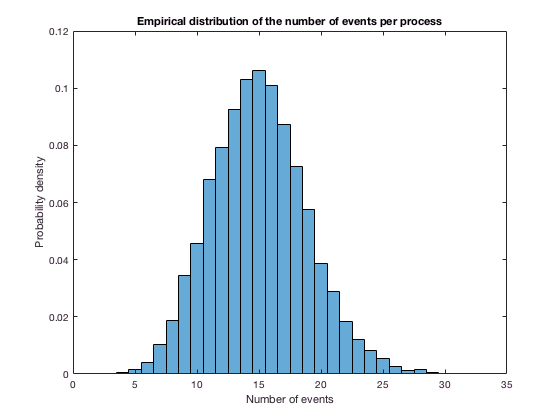

     histogram(data.nbEvents,'normalization', 'pdf');
         xlabel('Number of events');
         ylabel('Probability density');
         title('Empirical distribution of the number of events per process');

As expected, this empiral distribution closely follows a Poisson distribution of parameter lambda = rate x maxTime

## Occurrence times & intervals

An occurence time is the time at which an event has occurred.   All the exact occurrence times are contained in data.occurrenceTimes, which is a cell array of size N whose i-th element contains the occurrence times for all events of process i.  Thus, data.occurrenceTimes{i}(j) is the occurrence time of event j in process i.  For instance, 

    data.occurrenceTimes{3}

ans =     0.7260    1.3937    1.8232    1.9806    2.8175    4.0785    4.2284    4.2631    5.2407    5.5958    5.5995    5.6343    6.2190    6.6359    8.6398


is the list of all occurrence times for the 3rd process.   

An occurrence interval is the time interval that separates two consecutive events.    The infomation about the occurrence interval is easily found in the cell array data.occurrenceTimes.  More precisely, data.occurrenceIntervals{i}(j) is the time between events j and j-1 in process i.

     data.occurrenceIntervals{3}

ans =     0.7260    0.6677    0.4295    0.1573    0.8369    1.2610    0.1499    0.0347    0.9775    0.3552    0.0037    0.0348    0.5847    0.4169    2.0039


Occurrence times are particularly important in Poisson processes.   Indeed, the occurrence intervals in a Poisson process of rate lambda are independent and identically distributed random variables that follow the exponential distribution of mean 1/lambda.   To verify this fundamental property, one can simple create a histogram.  

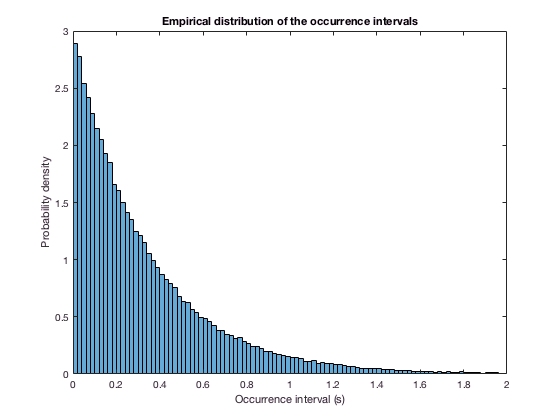

     histogram([data.occurrenceIntervals{:}]','normalization', 'pdf');
         xlabel('Occurrence interval (s)');
         ylabel('Probability density');
         title('Empirical distribution of the occurrence intervals');
         xlim([0 2]);

## Times series

    data.timeSeries is a N x T matrix, where N is the number of processes and T is the number of time steps.  timeSeries(i,j) is the nb of events that have occurred in process i at time step j     

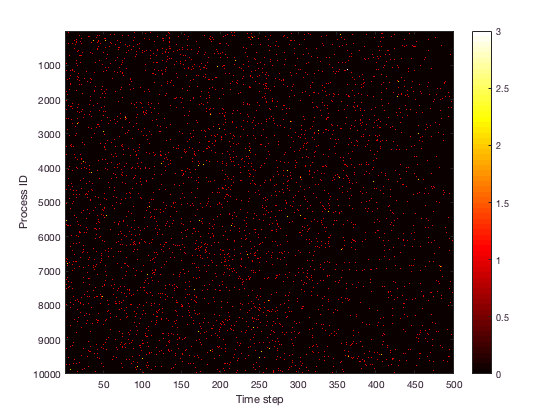

    imagesc(data.timeSeries);
    colormap('hot');
    colorbar;
    xlabel('Time step')
    ylabel('Process ID')

The information about the time steps is contained in two row vectors, data.timeValues  and data.timeEdges, which are such that 

- data.timeValues(j) is the mid-time in time step j;

- data.timeSequence(j) is the time at which ends time step j-1 and at which begins time step j.

    data.timeValues

ans =     0.0050    0.0150    0.0250    0.0350    0.0450    0.0550    0.0650    0.0750    0.0850    0.0950    0.1050    0.1150    0.1250    0.1350    0.1450    0.1550    0.1650    0.1750    0.1850    0.1950    0.2050    0.2150    0.2250    0.2350    0.2450    0.2550    0.2650    0.2750    0.2850    0.2950    0.3050    0.3150    0.3250    0.3350    0.3450    0.3550    0.3650    0.3750    0.3850    0.3950    0.4050    0.4150    0.4250    0.4350    0.4450    0.4550    0.4650    0.4750    0.4850    0.4950


    data.timeEdges

ans =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Thus, in order to plot the time series for the 3rd, we simply combine data.timeValues with data.timeSeries(3,:) as follows:

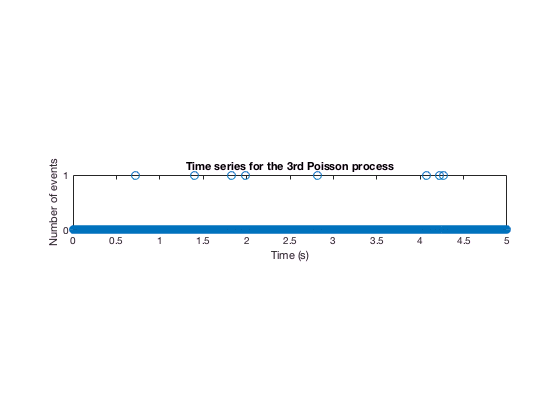

    figure()
    plot(data.timeValues, data.timeSeries(3,:),'o','MarkerSize',8);
    title('Time series for the 3rd Poisson process');
    xlabel('Time (s)');
    ylabel('Number of events');
    yticks([0 1 2 3 4]);
    pbaspect([4 0.5 2])